clf
clc
homedir='Z:\homes\Edita\Puncta_distributions\GNC_3month_turnover\Extracted_total_Part1';
% homedir='\Volumes\Users\homes\Edita\Puncta_distributions\GNC_3month_turnover\Day14\reorganized_by_region';

dirNameForFileName=strrep(homedir,'/','-slash-'); %if the dirName is in fact a path containing several directories, we substitute any / to the string -slash- as / is not a valid file name character
dirNameForFileName=strrep(dirNameForFileName,'\','-slash-');

delimiter='\t';
startRow = 2;


AllFile = dir(fullfile(homedir,'\*'))

AllFile = 1381×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


AllFile(1:2) = [];

region = 'FRP1';

Results_Day0=dir(sprintf(['totalIntensity_minValues_medianValues_3month_Day_0_',num2str(region),'.txt']));
Results_Day0 = readtable(Results_Day0.name);
Results_Day1_5=dir(sprintf(['totalIntensity_minValues_medianValues_3month_Day_1_5_',num2str(region),'.txt']));
Results_Day1_5 = readtable(Results_Day1_5.name);
Results_Day3=dir(sprintf(['totalIntensity_minValues_medianValues_3month_Day3_',num2str(region),'.txt']));
Results_Day3 = readtable(Results_Day3.name);
Results_Day7=dir(sprintf(['totalIntensity_minValues_medianValues_3month_Day_7_',num2str(region),'.txt']));
Results_Day7 = readtable(Results_Day7.name);
Results_Day14 =dir(sprintf(['totalIntensity_minValues_medianValues_3month_Day14_',num2str(region),'.txt']));
Results_Day14 = readtable(Results_Day14.name);



% % Day 0 data
Total_Day0 = Results_Day0(:,1);
Total_Day0 = table2array(Total_Day0);
mean_Day0=mean(Total_Day0)

mean_Day0 = 3.5792e+09

n_Day0 = length(Total_Day0);

% % Day 1.5 data
Total_Day1_5 = Results_Day1_5(:,1);
Total_Day1_5 = table2array(Total_Day1_5);
n_Day1_5 = length(Total_Day1_5);

% % Day 3 data
Total_Day3 = Results_Day3(:,1);
Total_Day3 = table2array(Total_Day3);
n_Day3 = length(Total_Day3);

% % Day 7 data
Total_Day7 = Results_Day7(:,1);
Total_Day7 = table2array(Total_Day7);
n_Day7 = length(Total_Day7);

% % Day 14 data
Total_Day14 = Results_Day14(:,1);
Total_Day14 = table2array(Total_Day14);
n_Day14 = length(Total_Day14);

%change the number that follows 'time_Day0' or 'time_Day7' with the N number for that time group
time_Day0=0;
time_Day0=repmat(time_Day0,n_Day0,1);
time_Day1_5=1.5;
time_Day1_5=repmat(time_Day1_5,n_Day1_5,1);
time_Day3=3;
time_Day3=repmat(time_Day3,n_Day3,1);
time_Day7=7;
time_Day7=repmat(time_Day7,n_Day7,1);
time_Day14=14;
time_Day14=repmat(time_Day14,n_Day14,1);


time_tot=[time_Day0
    time_Day1_5
    time_Day3
    time_Day7
    time_Day14];
Total_tot=[Total_Day0
    Total_Day1_5
    Total_Day3
    Total_Day7
    Total_Day14];
Total_tot=Total_tot';

Total_frac=1.*Total_tot/mean_Day0;


scatter(time_tot,Total_frac,'o','filled')
hold on
Total_frac=Total_frac';


f2 = fit(time_tot,Total_frac,'exp1');
[curvefit,gof,output] = fit(time_tot,Total_frac,'exp1')

curvefit =      General model Exp1:
     curvefit(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       1.112  (0.9221, 1.301)
       b =     -0.1048  (-0.1583, -0.05126)

gof = struct with fields:
           sse: 4.5309
       rsquare: 0.4768
           dfe: 37
    adjrsquare: 0.4627
          rmse: 0.3499


output = struct with fields:
           numobs: 39
         numparam: 2
        residuals: [39×1 double]
         Jacobian: [39×2 double]
         exitflag: 3
    firstorderopt: 0.0043
       iterations: 13
        funcCount: 28
     cgiterations: 0
        algorithm: 'trust-region-reflective'
         stepsize: 1.6862e-04
          message: 'Success, but fitting stopped because change in residuals less than tolerance (TolFun).'


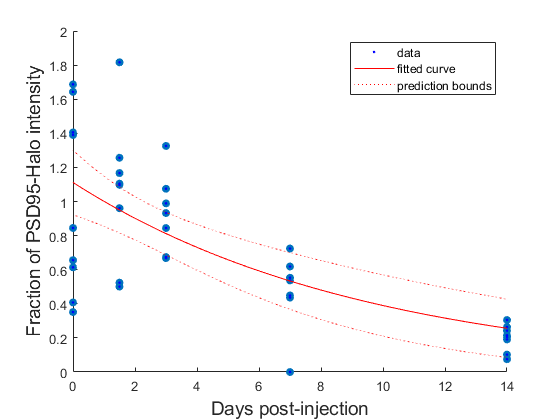

plot(f2,time_tot,Total_frac,'predfunc')
hold on
ylim([0;2])
xlabel('Days post-injection',"FontSize",14)
ylabel('Fraction of SiR-Halo intensity',"FontSize",14)
saveas(gcf,sprintf(['puncta_intensity_fraction_decay_3month_',num2str(region)]),'jpeg')%change the name as you wish
hold off

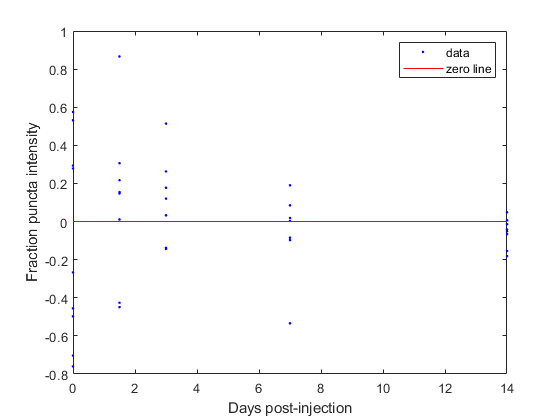



plot(curvefit,time_tot,Total_frac,'residuals')
hold on
xlabel('Days post-injection')
ylabel('Fraction puncta intensity')
saveas(gcf,sprintf(['puncta_intensity_decay_residuals_3month_',num2str(region)]),'jpeg')
hold off




halflife=0.693/(-(curvefit.b));
halflife

halflife = 6.6143

ci = confint(curvefit,0.95)'

ci =     0.9221    1.3012
   -0.1583   -0.0513


coef = [curvefit.a 
    curvefit.b];
coef_CI = [coef ci]

coef_CI =     1.1117    0.9221    1.3012
   -0.1048   -0.1583   -0.0513


title = {'a','b'};
writematrix(coef_CI,sprintf(['coefs_with_CI_puncta_count_decay_',num2str(region)]),"Delimiter",delimiter)
save(sprintf(['fitting_output_intensity_decay_',num2str(region)]),"curvefit","gof","output")
